# *The Cassini-Huygens Spacecraft*

The Cassini-Huygens mission was to study the planet Saturn and its moons. The payload consisted of the Cassini orbiter and the Huygens probe. The craft was launched in October 1997 and reached Saturn in 2004. Cassini-Huygens’ path consisted of four different gravity assist maneuvers.

% To see two plot answers, run this section.
openfig('cassiniPath1.fig','visible');
openfig('cassiniPath2.fig','visible');

## 1. Load the file `cassiniData1.mat`

Load the file `cassiniData1.mat`. This file contains column vectors for Time, Year, Month, Day, Radius, Latitude, and Longitude. (Time consists of year and fractional year and is included for ease of plotting against time.).

load("cassiniData1.mat");

## 2. Plot `Radius` vs. `Time` with a blue, dashed line

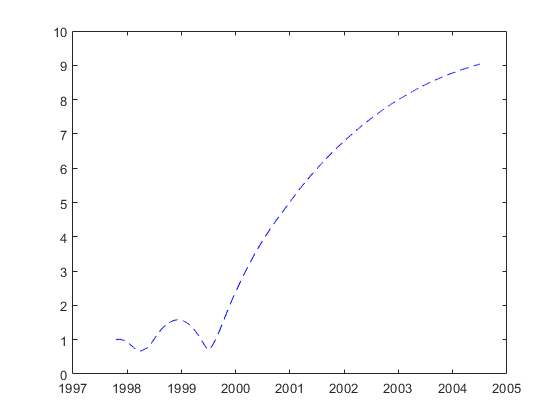

figure("Name","cassiniPath1")
plot(Time,Radius,'b--')

## 3. Add annotations

Add annotations to the plot including a title and *x*- and *y*-axis labels.

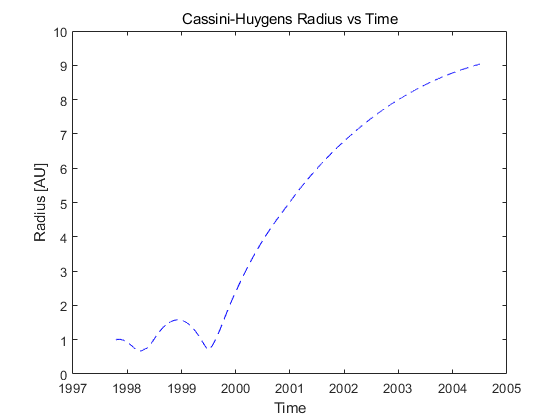

title("Cassini-Huygens Radius vs Time")
xlabel("Time")
ylabel("Radius [AU]")

## 4. Plot maximum radius

The maximum radius occurs at the final time. What is the maximum radius?

Plot the maximum as a red circle on the plot.

[maxRadius,idx] = max(Radius)

maxRadius = 9.0400

idx = 2450

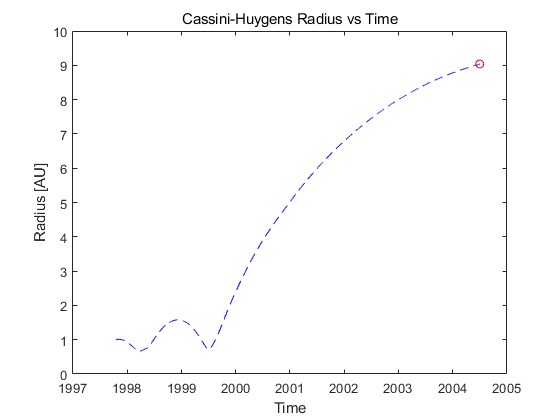


hold on
plot(Time(idx),maxRadius,"r-o")
hold off

## 5. Find Cassini's smallest distance to sun, and the year/day it happened

Using the `min` function, find the spacecraft’s smallest distance to the sun and the year and month that it occurred. Does this agree with the plot?

[minRadius,minidx] = min(Radius)

minRadius = 0.6700

minidx = 159

minyear=Year(minidx)

minyear = 1998

minday=Day(minidx)

minday = 23

minmonth =Month(minidx)

minmonth = 3

Display the smallest distance to the sun.

minRadius

minRadius = 0.6700

Display the year and month that the spacecraft was closest to the sun.

[minyear,minmonth]

ans =         1998           3


## 6. Plot the probe’s path in Cartesian coordinates.

##   a. Convert the latitude and longitude from degrees to radians.

       (**Hint** $1^\circ = \frac{\pi}{180}radians$)

%deg2rad(Latitude)
%deg2rad(Longitude)
rad_lat = (pi/180)*Latitude 

rad_lat =     0.1012
    0.0995
    0.0995
    0.0977
    0.0977
    0.0960
    0.0960
    0.0942
    0.0942
    0.0925


rad_long = (pi/180)*Longitude

rad_long =     5.3599
    5.3756
    5.3896
    5.4053
    5.4210
    5.4367
    5.4524
    5.4681
    5.4821
    5.4978


##   b. Convert Radius, Latitude, and Longitude to x,y,z 3D coordinates

       Use the `sph2cart` function to convert the probe location to *x*, *y*, and *z* coordinates, using the latitude and longitude in radians. (Note In spherical coordinates, latitude is also known as elevation, and longitude as azimuth.)

[x,y,z]= sph2cart(rad_long,rad_lat,Radius);

##   c. Plot x-y location

       Plot the probe’s *x*-*y* location and add appropriate annotations.

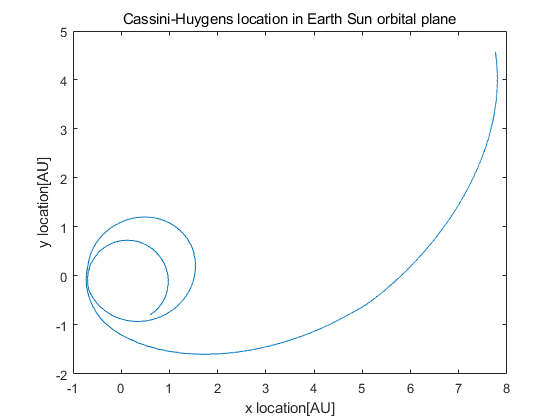

plot(x,y)
title("Cassini-Huygens location in Earth Sun orbital plane")
xlabel("x location[AU]")
ylabel("y location[AU]")